# Opgave 2

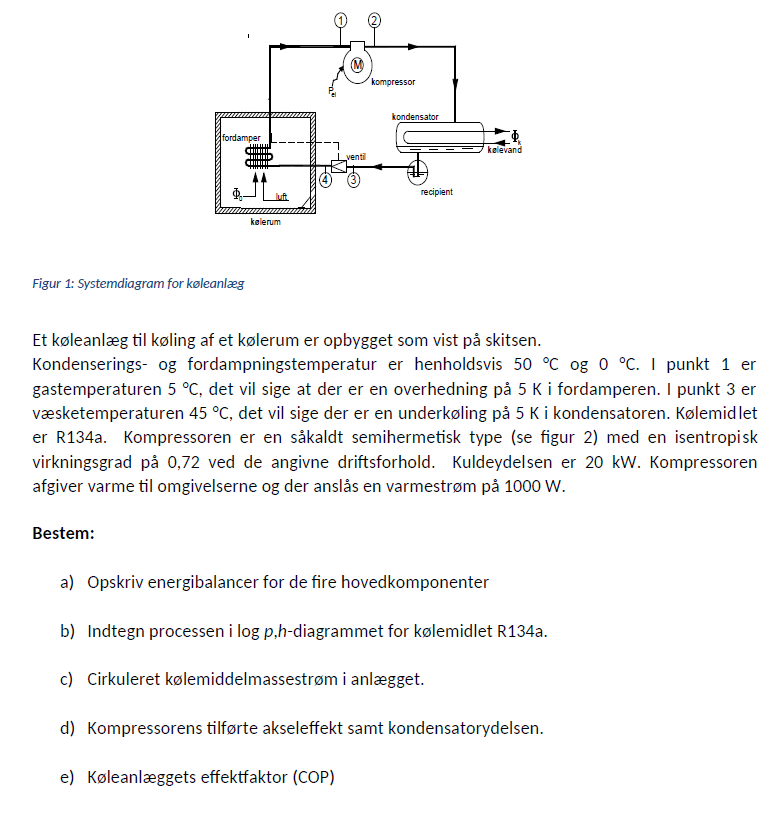

clc; clear all;

## Energibalancer


$$\dot{E}_{ind} + \dot{E}_{gen} - \dot{E}_{ud} = 0$$



$$\dot{E}_{gen} = 0$$



$$\dot{E}_{ind} = P_{el} + q_{m_{r134a}} \cdot h_1$$



$$\dot{E}_{ud} = q_{m_{r134a}} \cdot h_4 + \Sigma\Phi_{tab}$$


Hele anlægget


$$\Phi_0 + P_{el} - \Phi_{tab} = 0$$


**KF1: **Kompressor 1-2


$$P_{el} + q_{m_{r134a}} \cdot h_1 -  q_{m_{r134a}} \cdot h_2 - \Phi_{tab1} = 0$$


**KF2: **Kondensator 2-3


$$q_{m_{r134a}} \cdot h_2 -  q_{m_{r134a}} \cdot h_3 - \Phi_{tab2} = 0$$


**KF3: **Ekspansionsventil


$$q_{m_{r134a}} \cdot h_3 - q_{m_{r134a}} \cdot h_4 - \Phi_{tab3} = 0$$


**KF4: **Fordamper


$$\Phi_{slush} + q_{m_{r134a}} \cdot h_4 - q_{m_{r134a}} \cdot h_1 - \Phi_{tab4} = 0$$


**Rangering af **$\Phi_{tab}$


$$\Phi_{tab2} > \Phi_{tab1} > \Phi_{tab4} > \Phi_{tab1} $$


## Log p-h diagram

*Indsættes fra coolpack*

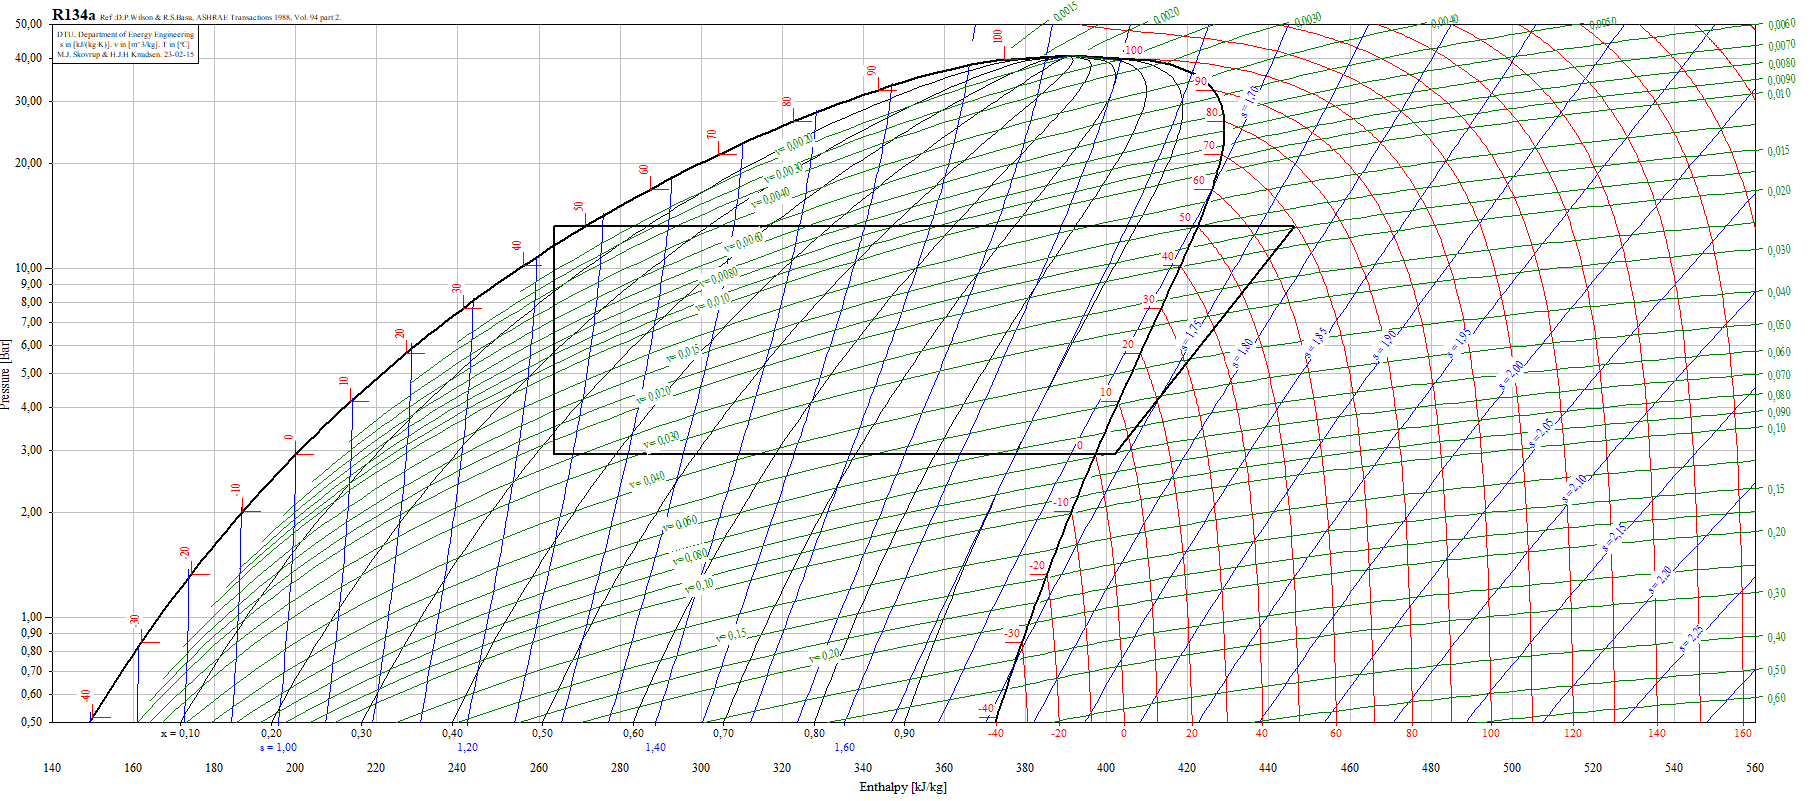

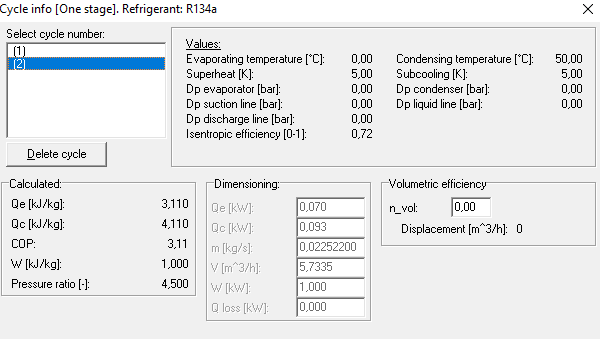

## Cirkuleret kølemiddelmassestrøm i anlægget

% Beregninger
u = symunit;
% Entalpier fra coolpack
h1 = 402.16 * u.kJ/u.kg; 
h2 = 446.06* u.kJ/u.kg;
h3 = 263.81* u.kJ/u.kg;
h4 = h3;

% Kompressor og specfik varmestrøm fra 4-1
kompressortab = 1 * u.kW

$$kompressortab = \mathrm{kW}$$

Phi_41 = 20 * u.kW - kompressortab;
q_41 = h1 - h4;


q_m_r134a = Phi_41/q_41

$$q\_m\_r134a = \frac{380}{2767}\,\frac{\mathrm{kW}\,\mathrm{kg}}{\mathrm{kJ}}$$



q_m_r134a = vpa(unitConvert(q_m_r134a,"SI"),3)

$$q\_m\_r134a = 0.137\,\frac{\mathrm{kg}}{s}$$

## Kompressorens tilførte akseleffekt samt kondensatorydelsen

wt_12 = h2 - h1;
akseleffekt = wt_12*q_m_r134a;
akseleffekt_12 = vpa(unitConvert(akseleffekt, u.kW), 3)

$$akseleffekt\_12 = 6.03\,\mathrm{kW}$$

## Køleanlæggets effektfaktor (COP)

wt_34 = h4 - h3 % ekspansionventilen ændrer ikke i entalpien

$$wt\_34 = 0$$

akseleffekt_34 = wt_34*q_m_r134a

$$akseleffekt\_34 = 0.0$$


COP = Phi_41/akseleffekt_12;
COP = vpa(COP, 3)

$$COP = 3.15$$